**6.6 ****Linear Prediction on the Stock Market **

Linear prediction is one of the most widely-used approaches to time series analysis involving applications such as speech coding, seismology, and frequency response modeling. In this exercise, you will learn how linear prediction can be used to design a discrete-time finite- length impulse response (**FIR**) filter to solve both a time-domain prediction problem and a frequency-domain modeling problem. 

In the prediction problem, you observe a signal $x[n] $ and wish to design a system that can predict future values of the signal based solely upon past values. For linear prediction, this system is an **FIR** filter which computes a prediction based upon a linear combination of past values, 

eq 6.27

                            
$$\hat{x}[n] = -\sum_{k=1}^{p}a_kx[n-k],$$
                        

where $\hat{x}[n]$ is the predicted value of $x[n]$. Since p previous values of the signal are used to formulate the prediction, this is a pth-order predictor. Given a fixed filter order, p, the linear prediction problem is to determine a set of filter coefficients, $a_k$, that best perform the prediction in Eq. (6.27). The most common measure of determining the "best" coefficients,  $a_k$, is to select those coefficients that minimize the total squared prediction error 

eq6.28

                        
$$E=\sum_{n=1}^{N} |e[n]|^2= \sum_{n=1}^{N} |x[n]-\hat{x}[n]  |^2,$$


assuming the sequence $x[n]$ has length **N**. Several approaches can be used to solve for the $a_k$'s  that minimize **E** in Eq. (6.28).  Perhaps the simplest is to use that MATLAB \ operator for solving simultaneous linear equations. Assuming $ N > P$ , the linear prediction problem can be posed in matrix form as 

Eq6.29

            
$$-\left[\matrix{ x[1]  &...   & x[p] \cr

x[2]  &...   & x[p+1] \cr
\vdots  & ...   & \vdots \cr
x[N-p]  &...   & x[N-1] \cr


} \right]


\left[\matrix{ a_1 \cr

\vdots \cr
a_p \cr


} \right]

+



\left[\matrix{ e[p+1] \cr
e[p+2] \cr
\vdots \cr
e[N] \cr


} \right]


=



\left[\matrix{ x[p+1] \cr
x[p+2] \cr
\vdots \cr
x[N] \cr


} \right]








$$
			

or compactly as `-Xa+e=x. `This equation can be used to solve for the vector **a **which minimizes the total squared prediction error, `e'*e. `The convention of incorporating the minus sign on the left hand side of Eq. (6.29) is so that the "prediction-error filter" can be expressed as `e=Xa+x `

			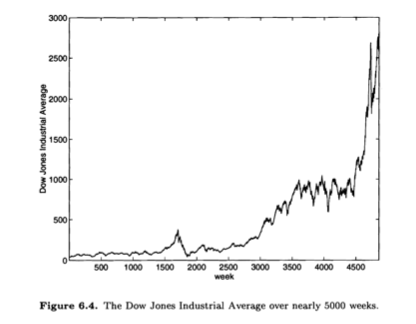

The problems in this exercise will apply linear prediction to the financial data stored in the file **djia.mat,** which is in the Computer Explorations Toolbox. If this file has been loaded correctly, then typing who should result in 				

**>> who**

**Your variables are: dj**

**djia **			

where **djia** is the Dow Jones Industrial Average (DJIA) index sampled weekly for approximately 94 years. The **DJIA** for these weeks is plotted in Figure 6.4. 

In this set of problems, you will attempt to make a fortune by investing with the following strategy: 

(i)  construct a linear predictor based on past DJIA data; 											

(ii)  use your predictor to guess the value of next week's DJIA based on the past p weeks; 										

(iii)  if the DJIA increases by more than the risk-free interest rate earned by a savings account, you invest all of your money in the DJIA; 						

(iv)  if the DJIA increases by less, you put all of your money in the bank. 						

You will assume that if you decide put all of your money in the **DJIA** for the week, then you will earn exactly the gain that was earned in the **DJIA**. For example, if you had $1000 in the **DJIA** at week $n$ and the DJIA at week $n+1$ was given by **djia(n+l)** , then at the end of week  $n+1$, you have **$1000*djia(n+l)/dj ia(n)**. Also assume that the savings account always earns ***r ***= **3% **annual interest, compounded weekly, i.e., your **$1000** would be worth** $1000*(1+0.03/52)** after one week in the bank. 

**Basic Problems **

(a).  Plot the **DJIA** data on both a linear and a semi-logarithmic scale. Assuming that you started with **$1000** and invested all of your money in the **DJIA**, how much money would you have at the end of the investment interval (4861 weeks)? If you had put all of your money in the bank at 3% annual percentage rate (APR),compounded weekly, what rate would you need to achieve the same level of performance? If $ r = 0.03$ is the APR, then the bank balance after N weeks from a weekly compounded interest bearing account is equal to $g=(1+r/52)^N$ the initial balance. 						

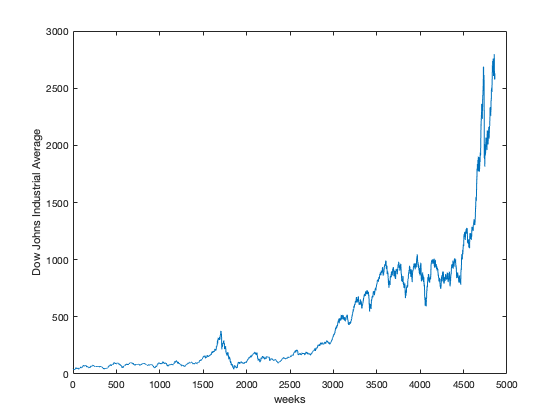

clf;
clc;
load djia.mat

figure(1);
plot(djia);xlabel('weeks');ylabel('Dow Johns Industrial Average');

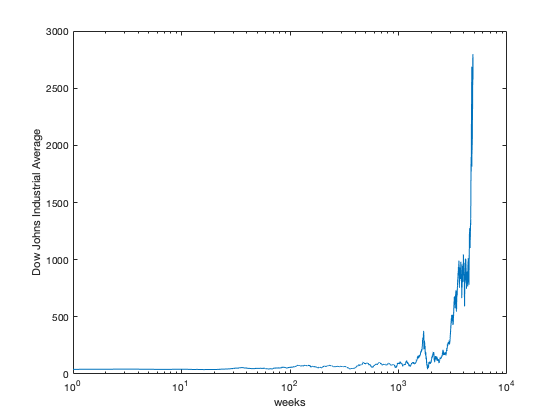

clf ;figure(2); semilogx(djia);xlabel('weeks');ylabel('Dow Johns Industrial Average');

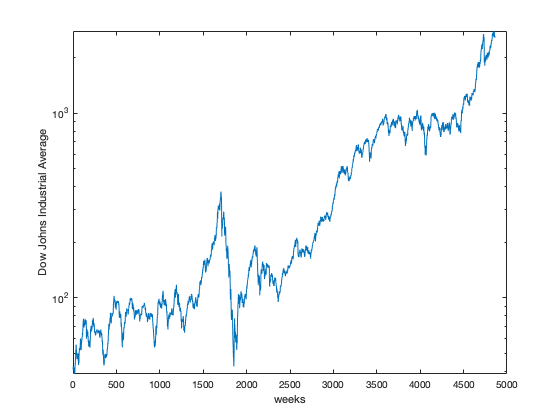

clf;figure(3); semilogy(djia); xlabel('weeks');ylabel('Dow Johns Industrial Average');

clf;
money=1000;
N=length(djia);
week=1:N;

djiasaving=zeros(1,N);
djiasaving(1)=money;
for i=2:N
    djiasaving(i)=djiasaving(i-1)*djia(i)/djia(i-1);
end
r=3;

banksaving=zeros(1,N);
banksaving(1)=money;
for i=2:N
    
    banksaving(i)=money*(1+r/(100*52))^(i-1);
end


fprintf('p after investing in djia %f\n', djiasaving(N-1))

p after investing in djia 63199.412053


fprintf('p after investing in saving account  %f', banksaving(N-1))

p after investing in saving account  16485.165342

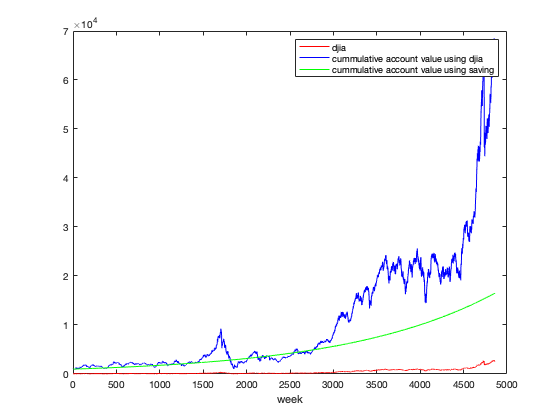

clf;
figure(4);

plot(week,djia,'r',week,djiasaving,'b',week,banksaving,'g');
legend('djia','cummulative account value using djia','cummulative account value using saving');
xlabel('week');

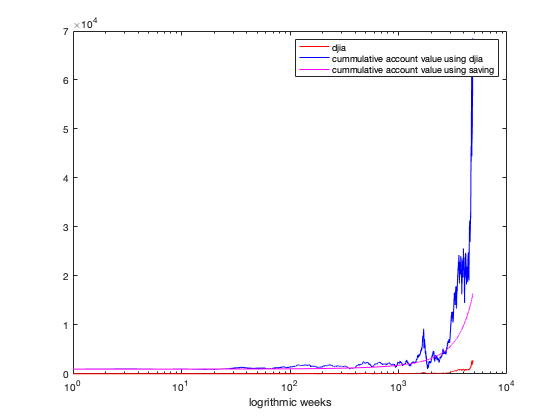

clf;
figure(5);
semilogx(week,djia,'r',week,djiasaving,'b',week,banksaving,'m');
legend('djia','cummulative account value using djia','cummulative account value using saving');
xlabel('logrithmic weeks');

%djia = con2seq(djia);
time = 1:length(djia);  
djia=djia';

numTimeStepsTrain = floor(0.9*numel(djia));

dataTrain = djia(1:numTimeStepsTrain+1);
dataTest = djia(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 520;

layers = [
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',300,  ...
    'GradientThreshold',1,  ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
     'Verbose',0, 'Plots','training-progress');

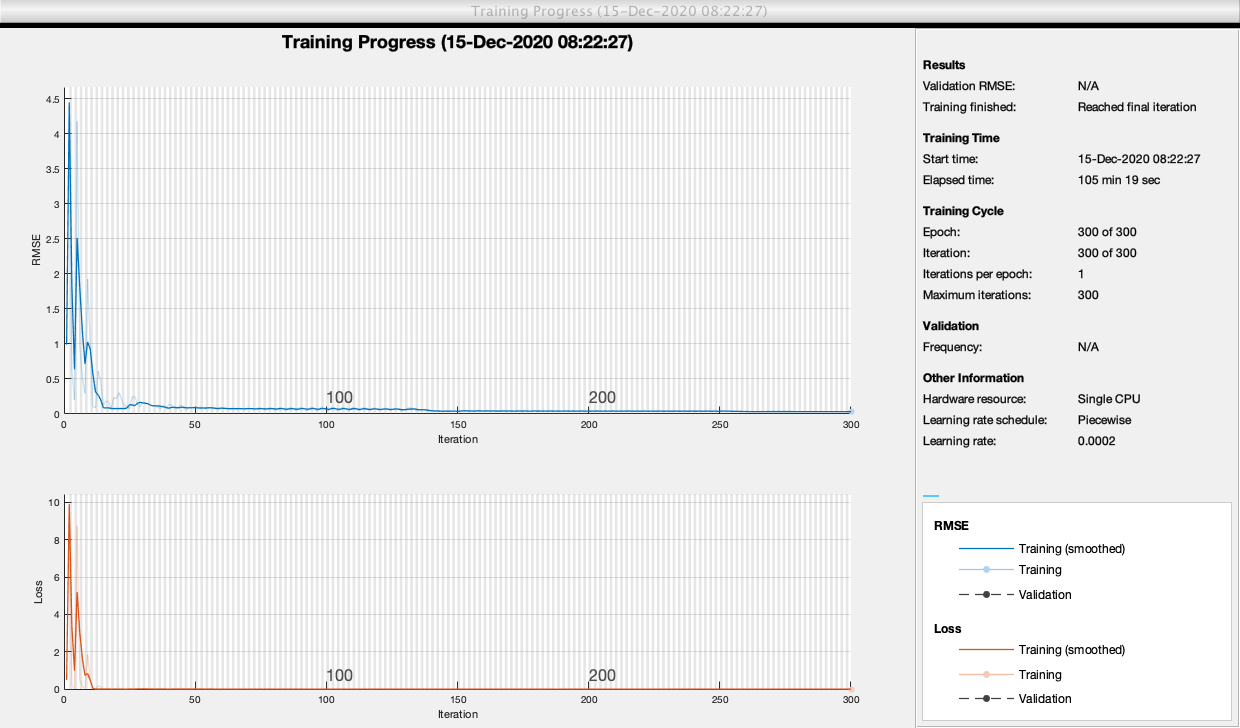

net = trainNetwork(XTrain,YTrain,layers,options);

dataTestStandardized = (dataTest - mu) / sig;

XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

YTest = dataTest(2:end);

rmse = sqrt(mean((YPred-YTest).^2))

rmse = single
881.1624

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;
rmse = sqrt(mean((YPred-YTest).^2))

rmse = 261.9408

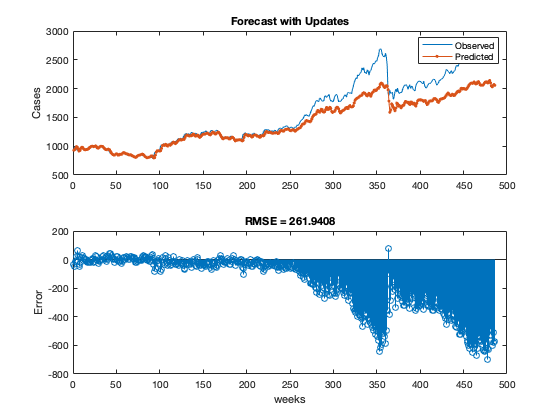

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("weeks")
ylabel("Error")
title("RMSE = " + rmse)

**Intermediate Problems **

(e). Given the predictor you designed based on the first decade of data and the model order you have selected from Part (d), you will now test the investment strategy outlined in the introduction. Give yourself $1000 at the end of the p th week, and make 520 trading decisions based on the output of your predictor. First, determine an upper bound on the amount of money you could make. This would be how much you could make if you were omniscient, i.e., if you knew which direction the stock market was going each week and were always invested in the better of either the bank or the DJIA. Now, as a lower bound, calculate how much money you would make if you left all of your money in the bank and earned a gain of (1+0.03152) each week. As another lower bound, determine how much you would make with the "buy-and-hold" strategy, where you put all your money in the DJIA every week. Finally, calculate how much money you would make with your predictor. What is the equivalent APR that the bank would have had to pay you to achieve the same gain as your predictor? 

[lb,ub] = bounds(YPred); %lower bound and upper bound
fprintf('Upper Bound is %f\n', ub);

Upper Bound is 934.042175


fprintf('Lower Bound is %f\n', lb);

Lower Bound is 930.985474


% New APR 
banksaving2=zeros(1,N);
banksaving2(1)=money;
for i=2:520
    banksaving2(i)=money*((1+0.03152)^(i));
end
a=banksaving2(520)*100;

apr_rate=lb/a;
apr_rate % APR is %2.09

apr_rate = 2.0994e-09

%
% Investment Strategy
%

savings_weeks=zeros(1,10);
investing_saving = 0;
N=485;
for p=1:10 % for 10th week
    
    for i = 1:p:N-p
        if(djia(i+p)<djia(i+p+1))
            investing_saving = investing_saving + 1000*(YPred(i+p+1))/(YPred(i+p));
        elseif(djia(i+p)>djia(i+p+1))   
            investing_saving = investing_saving + 1000*(1 +0.03/52);
        end
    end
    savings_weeks(p)=investing_saving;
    
end
[lb3,ub3] = bounds(savings_weeks) ;
fprintf('Upper Bound is %f\n', ub3);

Upper Bound is 1405333.500000


fprintf('Lower Bound is %f\n', lb3);

Lower Bound is 481116.812500



savings_weeks2=zeros(1,10);
investing_saving2 = 0;

for p=1:10 % for pth week
    
    for i = 1:p:N-p
        if(djia(i+p)<djia(i+p+1))
            investing_saving2 = investing_saving2 + 1000*(YPred(i+p+1))/(YPred(i+p));
        elseif(djia(i+p)>djia(i+p+1))   
            investing_saving2 = investing_saving2 + 1000*(1 +0.03/52);
        end
    end
    savings_weeks2(p)=investing_saving2;
    
end
[ub4,lb4] = bounds(savings_weeks2); 
fprintf('Upper Bound is %f\n', ub4);

Upper Bound is 481116.812500


fprintf('Lower Bound is %f\n', lb4);

Lower Bound is 1405333.500000


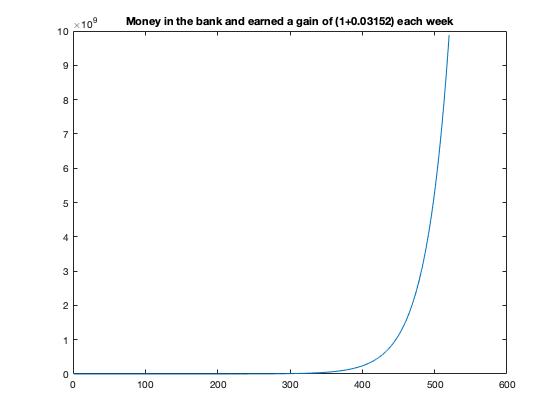

clf;
clc;
banksaving2=zeros(1,N);
banksaving2(1)=money;
for i=2:520
    banksaving2(i)=money*((1+0.03152)^(i-1));
    
end

plot(banksaving2);title('Money in the bank and earned a gain of (1+0.03152) each week');

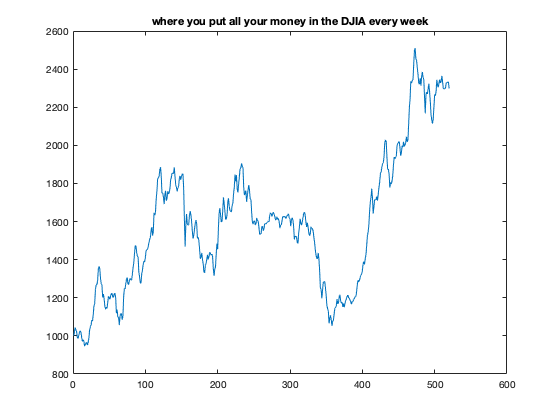

clf;
clc;
djiasaving2=zeros(1,N);

djiasaving2(1)=money;
for i=2:520
    djiasaving2(i)=djiasaving2(i-1)*djia(i)/djia(i-1);
    
end

plot(djiasaving2);title('where you put all your money in the DJIA every week');

(f). Now use your prediction strategy on the most recent decade in the data, i.e., the last 520 weeks of the DJIA. Calculate how you did and how each of the bounds perform: 			

best-possible,all in the bank account, and buy-and-hold. Also calculate the equivalent APR for your predictor. 

banksaving3=zeros(1,N);
banksaving3(1)=money;
dl=length(djia);
k=1;
N=520;

N = 520

for i=dl-N:dl
    
    banksaving3(k)=money*((1+0.03152)^(i));
    k=k+1;
    
end
a=banksaving3(520)*100;

apr_rate=lb/a;
apr_rate % APR is %2.39 

apr_rate = single
0

### **Advanced Problems**

(g). Compute the maximum gain possible over all of the data. That is if you knew what the DJIA was going to do each week, and you had the option of making (1+*0.03152) *in the bank, or the weekly gain in the DJIA, how much could you make over all 4861 weeks? 

*(You may be motivated now to look for additional prediction strategies that could come closer to this maximum gain than the simple linear prediction scheme developed in previous parts. For example, you might try updating your predictor coefficients based on the most recent decade before making each prediction. There are several fast algorithms for doing exactly this, like the recursive least squares (RLS) algorithm. )*


max_gain=1000;
for i = 1:dl-1
    if(djia(i)<djia(i+1))
        max_gain = (max_gain*((djia(i+1))/(djia(i))));
    elseif(djia(i)>djia(i+1))   
        max_gain = max_gain*(1 + 0.03/52);
    end
end

fprintf('Maximum gain over all week: %f', max_gain)

Maximum gain over all week: 372778221772277678080.000000

(h). Show that the linear predictor can be used to model the DTFT of the sequence ***x[n]  ***by analytically demonstrating (using Parseval's relation) that the coefficients `ak `are chosen to 

      minimize 

	                	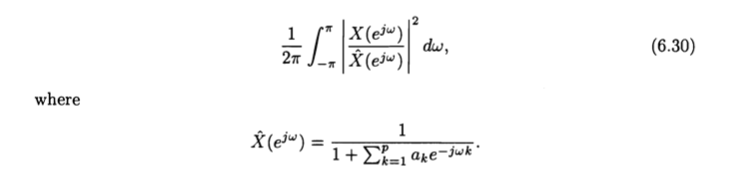		

Plot the DTFT of the DJIA sequence and the frequency response of the linear predictor on the same set of axes. Since it is not the difference, but rather the ratio, that is minimized, you should see that $\hat{X}(e^{j\omega})$ has the proper shape, but is off by a scale factor **G**. Scale $\hat{X}(e^{j\omega})$ by $G = \sum e^2[n]$ and re-plot the two DTFTs. Can you figure out why this value of **G** was chosen? 

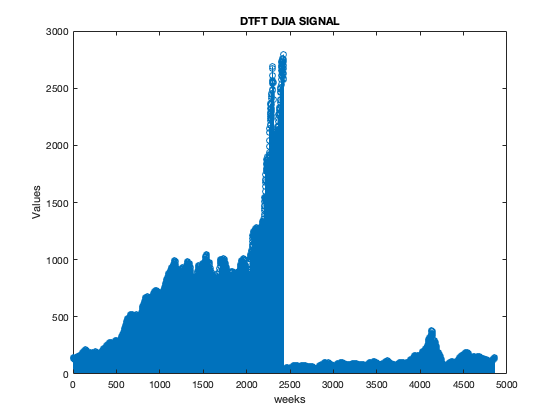

clf;
X= fftshift(djia); % dtfs representation
figure;
stem(X); title('DTFT DJIA SIGNAL'); xlabel('weeks');ylabel('Values');

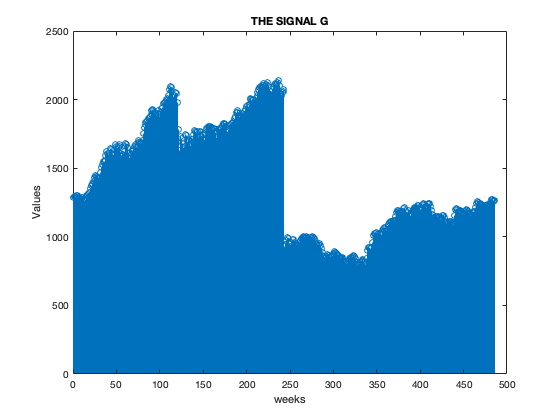

clf;
G= fftshift(YPred); %  
figure;
stem(G); title('THE SIGNAL G'); xlabel('weeks');ylabel('Values');